% Výpočet hodnot
Lval = L.Value;
Rval = R.Value;
keval = ke.Value;
Jval = J.Value;
kmval = km.Value;
bval = b.Value;
Lgval = Lg.Value;
Rgval = Rg.Value;
kegval = keg.Value;
kmgval = kmg.Value;
bgval = bg.Value;

% Matice A
A = [
    -Rval/Lval,        0,       -keval/Lval,     0;
    0,         -Rgval/Lgval,   -kegval/Lgval,    0;
    kmval/Jval,  kmgval/Jval, -(bval+bgval)/Jval, 0;
    0,              0,             1,             0
];

% Matice B (3 vstupy: um, ug, mz)
B = [
    1/Lval,    0,          0;
    0,      1/Lgval,       0;
    0,        0,        -1/Jval;
    0,        0,           0
];

% Matice C (výstup: omega)
C = [0 0 1 0];

% Matice D
D = [0 0 0];

% Přenos pouze z um => omega
sys = ss(A, B(:,1), C, D(1));

% Převod na přenosovou funkci
G = tf(sys)

G =
 
        3.333e04 s + 3.333e05
  ----------------------------------
  s^3 + 28.39 s^2 + 7879 s + 1.17e05
 
Continuous-time transfer function.
Model Properties


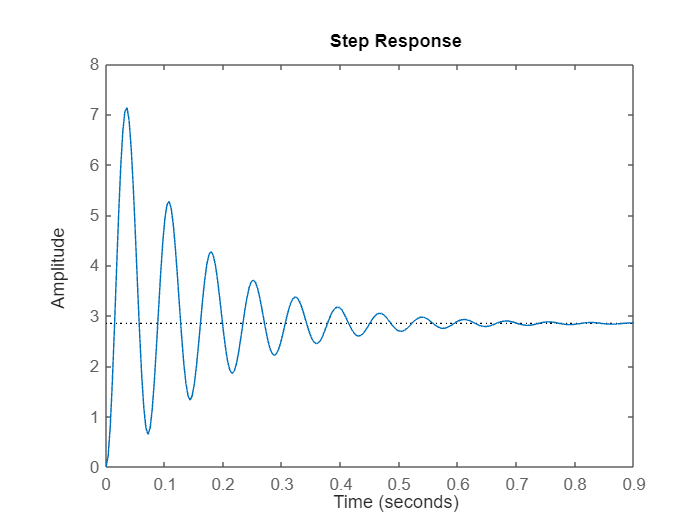

step(G)